# Mauna Loa Carbon Dioxide Concentration

This data is from the official [website](https://gml.noaa.gov/ccgg/trends/data.html).

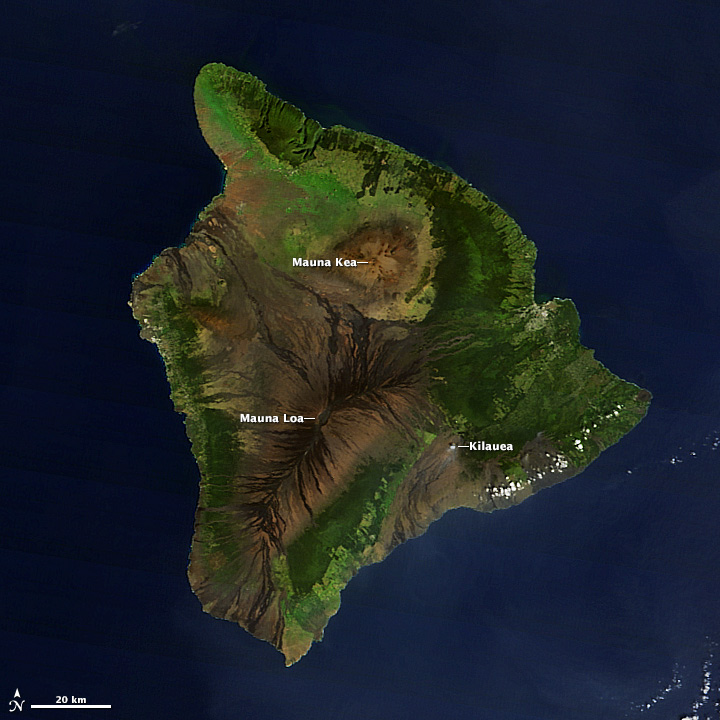

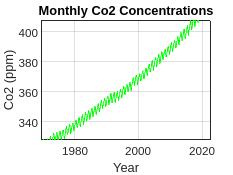

co2=xlsread("co2_mauna_loa.xlsx");
year=co2(:,3);
co2=co2(:,4);
plot(year,co2,'g');
grid on;
title("Monthly Co2 Concentrations");
xlabel("Year");
ylabel("Co2 (ppm)");

xlim([1969.4 2022.8])
ylim([327.9 407.9])

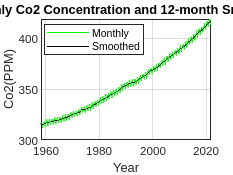

window=12;
smooth=smoothdata(co2,'movmean',window);
plot(year,co2,'g',year,smooth,'k');grid on;
title(sprintf("Monthly Co2 Concentration and %d-month Smoothing",window));
xlabel("Year");ylabel("Co2(PPM)");
legend("Monthly","Smoothed","location","best");

model=fittype('a+b*exp(n*(year-1958)','Independent','year');

'fittype' requires Curve Fitting Toolbox.

options=fitoptions('Method','NonlinearLeastSquares','StartPoint',[0 0 0]);
co2_fit=fit(year,co2,model,options);
co2_model=co2_fit.a+co2_fit.b * exp(co2_fit.n *(year-1958));
plot(year,smoothed,'k',year,co2_model,'r--');
title("Co2 smoothed and co2 model");
xlabel("Year");ylabel("Co2(PPM)");
legend("Smoothed","Model","location","best");

future=year(end):(1/12):2050;
co2_future=co2_fit.a +co2.fit.b *exp(co2.fit.n *(future-1958));
plot(year,co2,'g',future,co2_future,'r--');grid on;
title("Co2 smoothed and co2 model");
xlabel("Year");ylabel("Co2(PPM)");
legend("Smoothed","Model","location","best");
